Gradient descent

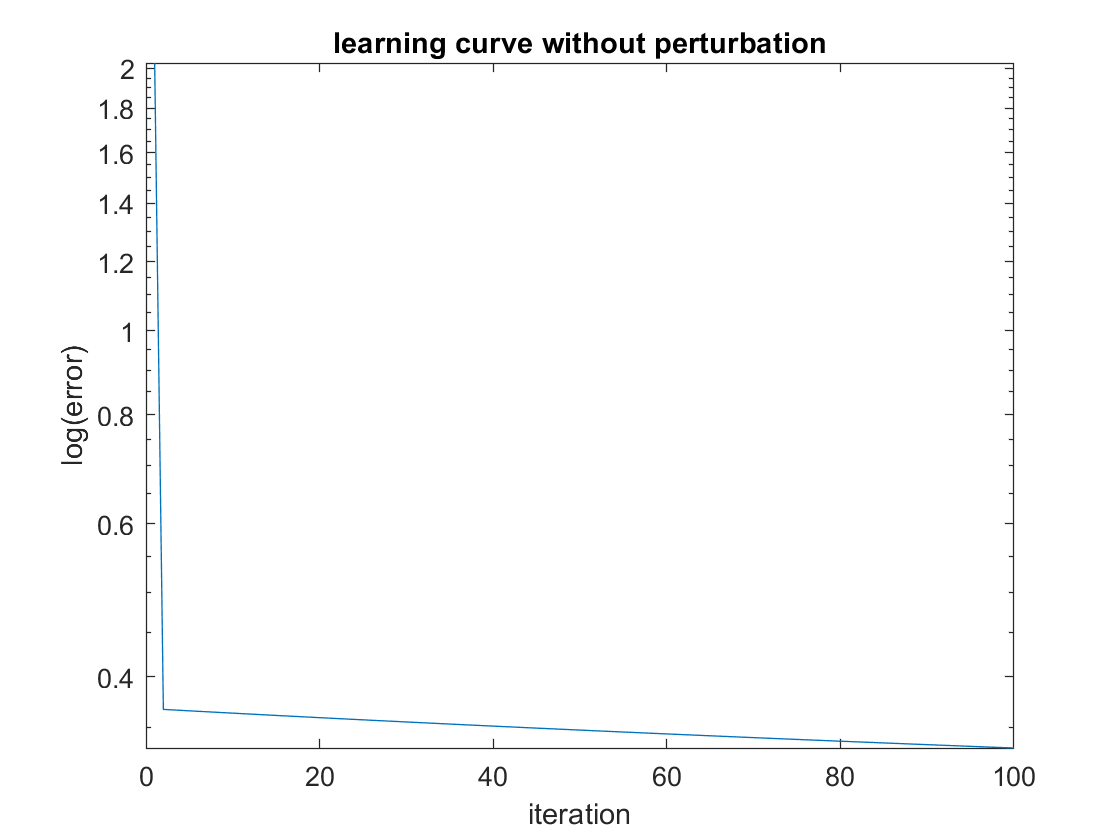

%% gradient no perturbation
n = 10;
m = 20;
%for j =1:10
iter = 100;
itag = 1/(2+n);
% rng('default');
% rng(2019);
w = 0.01*rand(m,n);
% rng('default');
% rng(34);
d = rand(m,1);
%W = w-wtarget;
% rng('default');
% rng(6);
x = normrnd(0,1,[n,1]);
etraj = zeros(1,iter);
for i = 1:iter
    e = 0.5*sum((d-tanh(w*x)).^2);
    etraj(i) = e;
deltawg = -itag*((tanh(w*x)-d)/cosh(sum(w*x))^2)*x';
w = w + deltawg;
end 
figure
semilogy(etraj);
xlabel('iteration');
ylabel('log(error)');
title('learning curve without perturbation');

%end

% fite = log10(etraj);
% [k, intercept] = polyfit(1:1:9,fite(1:9),1);

Node perturbation

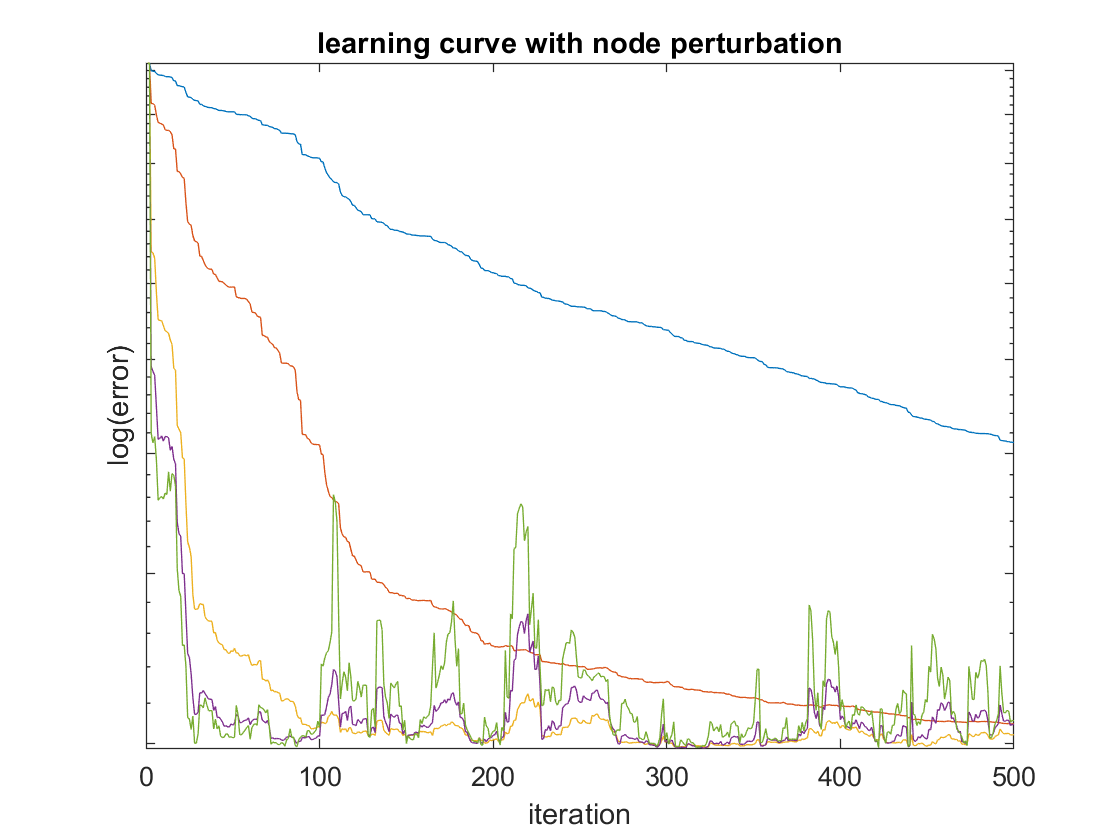

%% node perturbation 
figure
n = 10;
m = 10;
sigma = 0.01;
iter = 500;
lambda1 = [0.02 0.1 0.5 1 2];
%itanp = (1/((m+h+2)*(n+2)))*lambda;
for p = 1:length(lambda1)
itanp = (1/((m+2)*(n+2)))*lambda1(p);
num_run = 100;
etraj_all = zeros(num_run, iter);
for j = 1:num_run
w = 0.01*rand(m,n);
rng('default');
rng(2);
w_star = rand(m,n);
x = normrnd(0,1,[n,1]);
d = w_star*x;
etraj = zeros(1,iter);
for i = 1:iter
enp = normrnd(0,sigma,[m,1]);
eper2 = 0.5*norm(d-(tanh(w*x)+enp))^2;
e = 0.5*norm(d-tanh(w*x))^2;
%g_e = norm(tanh(w)-w_star)^2;
etraj(i) = e;
deltawnp = -(itanp/sigma^2)*(eper2-e)*enp*x';
w = w+deltawnp;
end
if etraj(end) <= etraj(1)
etraj_all(j,:) = etraj;
end
end
etraj_all = etraj_all(any(etraj_all,2),:);
etraj_avg = mean(etraj_all);
semilogy(etraj_avg);
hold on;
xlabel('iteration');
ylabel('log(error)');
title('learning curve with node perturbation');
set(gca,'YTickLabel',[]);
end




fite = log10(etraj);
[k, intercept] = polyfit(1:1:150,fite(1:150),1);